clear
clc
pose = dir("pose");
depth = dir("depth");
size = size(pose,1)

size = 3707

fid = 3

imgname = '/Users/sheelsansare/Downloads/area_3/data/depth/camera_04a287849657478ea774727e5bff5202_office_3_frame_0_domain_depth.png'

max_val = 1002

temp =     0.4890    0.4880    0.4880    0.4880    0.4880    0.4870    0.4870    0.4870    0.4870    0.4860    0.4860    0.4860    0.4860    0.4860    0.4850    0.4850    0.4850    0.4850    0.4840    0.4840    0.4840    0.4840    0.4830    0.4830    0.4830    0.4830    0.4820    0.4820    0.4820    0.4820    0.4820    0.4810    0.4810    0.4810    0.4810    0.4800    0.4800    0.4800    0.4800    0.4790    0.4790    0.4790    0.4790    0.4780    0.4780    0.4780    0.4780    0.4780    0.4770    0.4770
    0.4890    0.4880    0.4880    0.4880    0.4880    0.4870    0.4870    0.4870    0.4870    0.4860    0.4860    0.4860    0.4860    0.4860    0.4850    0.4850    0.4850    0.4850    0.4840    0.4840    0.4840    0.4840    0.4830    0.4830    0.4830    0.4830    0.4820    0.4820    0.4820    0.4820    0.4810    0.4810    0.4810    0.4810    0.4810    0.4800    0.4800    0.4800    0.4800    0.4790    0.4790    0.4790    0.4790    0.4780    0.4780    0.4780    0.4780    0.4780    0.4770  

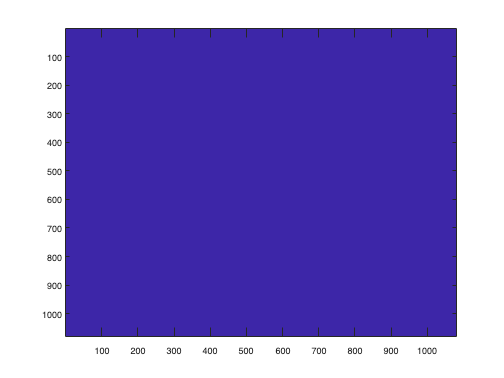

for i = 4:4
    fname = append(pose(i).folder, '/', pose(4).name);
    fid = fopen(fname)
    raw = fread(fid,inf); 
    str = char(raw'); 
    fclose(fid); 
    val = jsondecode(str);
    imgname = append(depth(i).folder, '/', depth(4).name)
    img_raw = imread(imgname);
    img = double(imread(imgname))/512.0; % depth in meters
    histogram(img)
%     disp(max(img))
%     disp(min(img))
    img_raw_float = double(img_raw);
    
    max_val = max(img_raw_float,[],'all')
    temp = img_raw_float / max_val
%     disp(double(imread(imgname))/max_val)
    image(double(imread(imgname))/max_val)
    
end